# Item 2 

## Enunciado

**Para el caso del avión, emplear un tiempo de integración por Euler adecuado y un tiempo de**

**simulación de 70seg. Los parámetros son **$a=0.07; \omega=9; b=5; c=150$** hallar un controlador para que**

**los polos de lazo cerrado se ubican en **$u_i=-15\pm15j; -0.5\pm0.5j$**, para referencias de 100 y -100 metros en altura, ambas con alturas iniciales de -500 y 500.**

- Proponer un controlador en tiempo discreto en variables de estado para que el proceso evolucione en los rangos de validez del modelo, es decir donde los ángulos y el valor de la acción de control en valor absoluto son menores a la unidad.

- Establecer el valor del tiempo de muestreo más adecuado para implementar el diseño en un sistema micro controlado.

- Determinar el efecto de la nolinealidad en la acción de control, descripta en la Fig. 4, y verificar cuál es el máximo valor admisible de la nolinealidad.

- Asumiendo que no puede medirse el ángulo $\alpha$, pero sí el ángulo $\phi$y la altura, proponer un esquema que permita lograr el objetivo de control.

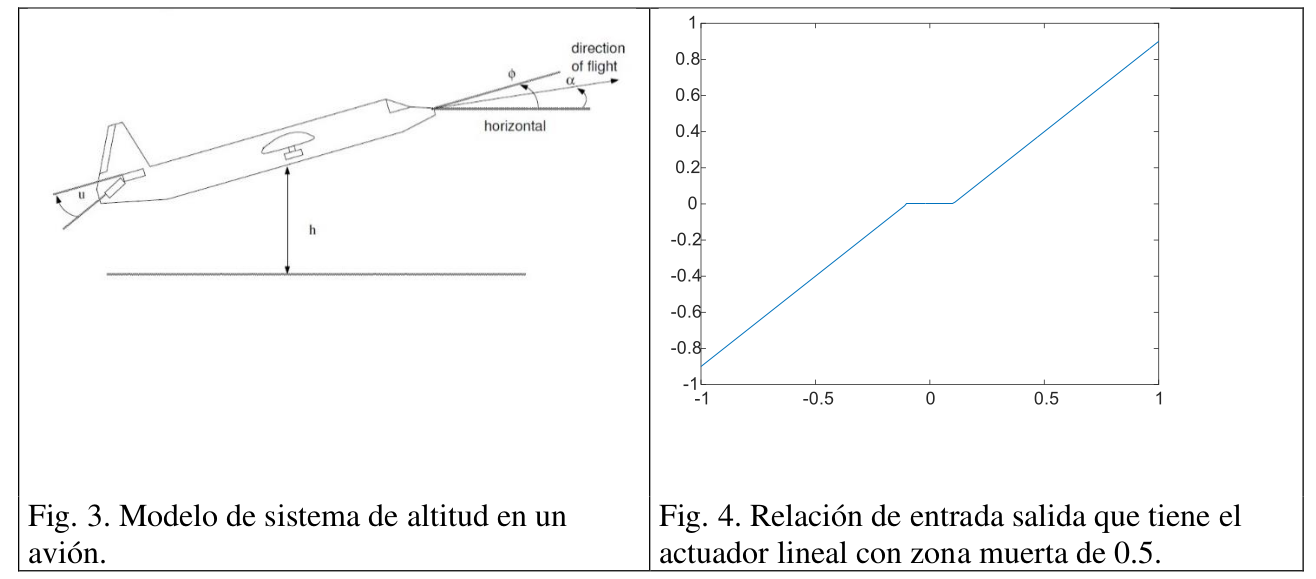

## Resolución

Se plantea el modelo en variables de estado del avión a partir de las constantes propuestas.

clear all; close all; clc
a = 0.07;
b = 5;
c = 150;    % velocidad de vuelo [m/s]
w = 9;  

Ac = [-a    a   0 0;    % alpha
       0    0   1 0;    % phi
      w^2 -w^2  0 0;    % phi_p
        c   0   0 0];   % h
Bc = [0 0 b*w^2 0]';

Cc = [0 0 0 1;
      0 1 0 0];             %salida altura y phi
Dc = 0;

A partir del analisis de la matriz controlabilidad, se determina si el sistema es controlable para $n = 4$ variables de estado.

Mc = [Bc Ac*Bc Ac^2*Bc Ac^3*Bc]

Mc = 	1.0e+04 *

         0         0    0.0028   -0.0002
         0    0.0405         0   -3.2805
    0.0405         0   -3.2805    0.2296
         0         0         0    0.4253


rank(Mc)

ans = 4

El sistema es controlable. Se procede a diseñar un controlador mediante ubicacion de polos. Se utiliza la ley de control lineal de tipo $u = -Kx + Gref$

% Diseño del controlador
p1 = -15+15i;
p2 = -15-15i;
p3 = -0.5+0.5i;
p4 = -0.5-0.5i;    
poles = [p1 p2 p3 p4];

pc = poly(eig(Ac));
W = [pc(4) pc(3) pc(2) 1; pc(3) pc(2) 1 0; pc(2) 1 0 0; 1 0 0 0];  
T = Mc*W;

eq = poly(poles);
K = (fliplr(eq(2:end)-pc(2:end))*inv(T));

G=-inv(Cc(1,:)*inv(Ac-Bc*K)*Bc);

Se procede a simular el sistema. Se debe obtener el tiempo de la dinamica mas rápida para definir el tamaño de paso en la integración de Euler.

% Tiempos de simulacion
log(0.95)/real(max(eig(Ac)))

ans = 1.4655

delta = 0.01

delta = 0.0100

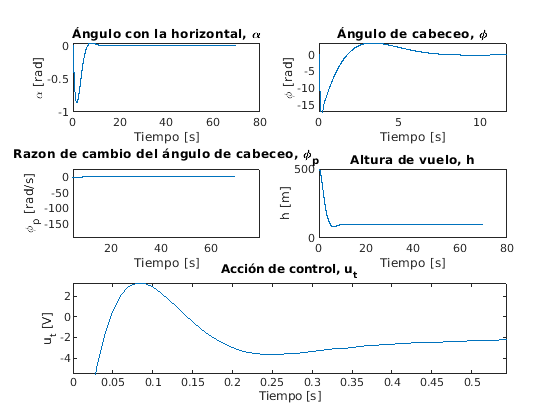

tsim = 70;
N = floor(tsim/delta);
t = 0:delta:(tsim-delta);

% Prealocación de arrelgos
alpha = zeros(1,N);
phi = zeros(1,N);
h = zeros(1,N);
phi_p = zeros(1,N);
u = zeros(1,N);

% Valores iniciales y referencia
ref = 100;
x = [0; 0 ; 0 ; 500];

% Simulación
for i=1:N
   
   y_out = Cc*x;
   u(i) = -K*x+G*ref;   

   x_p = Ac*x + Bc*u(i);     
   x  = x + x_p*delta;    
   

   alpha(i) = x(1);
   phi(i)   = x(2);
   phi_p(i) = x(3);
   h(i)     = x(4);    
  
  
   x = [alpha(i); phi(i); phi_p(i); h(i)];
end

figure(1);

subplot(3,2,1); grid on; 
plot(t, alpha);
title('Ángulo con la horizontal, \alpha');
ylabel('\alpha [rad]');
xlabel('Tiempo [s]');

subplot(3,2,2); grid on; 
plot(t, phi);
title('Ángulo de cabeceo, \phi');
ylabel('\phi [rad]');
xlabel('Tiempo [s]');

subplot(3,2,3); grid on; 
plot(t, phi_p);
title('Razon de cambio del ángulo de cabeceo, \phi_p');
ylabel('\phi_p [rad/s]');
xlabel('Tiempo [s]');

subplot(3,2,4); grid on; 
plot(t, h);
title('Altura de vuelo, h');
ylabel('h [m]');
xlabel('Tiempo [s]');

subplot(3,1,3); grid on; 
plot(t, u);
title('Acción de control, u_t');
ylabel('u_t [V]');
xlabel('Tiempo [s]');

Se puede observar a partir del sistema simulado que las magnitudes del sistema no son menores a la unidad. Esto implica que el modelo ya no es válido para el sistema planteado.

Se plantea un controlador LQR discreto para cumplir con la especificación dada. A partir del sistema discreto:

tR = log(0.95)/real(max(eig(Ac)))

tR = 1.4655

Tm = tR/10

Tm = 0.1466


G = ss(Ac, Bc, Cc, Dc)


G =
 
  A = 
          x1     x2     x3     x4
   x1  -0.07   0.07      0      0
   x2      0      0      1      0
   x3     81    -81      0      0
   x4    150      0      0      0
 
  B = 
        u1
   x1    0
   x2    0
   x3  405
   x4    0
 
  C = 
       x1  x2  x3  x4
   y1   0   0   0   1
   y2   0   1   0   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



Gd = c2d(G, Tm , 'zoh');
Ad = Gd.a

Ad =     0.9925    0.0075    0.0006         0
    0.7483    0.2517    0.1077         0
    8.6716   -8.6716    0.2517         0
   21.8858    0.0970    0.0050    1.0000


Bd = Gd.b

Bd =     0.0136
    3.7553
   43.6198
    0.0770


Cd = Gd.c

Cd =      0     0     0     1
     0     1     0     0


Dd = Gd.d

Dd =      0
     0


Se introduce un integrador al controlador.

Aa = [Ad , zeros(4,1) ; -Cd(1,:)*Ad, eye(1)];
Ba = [Bd; -Cd(1,:)*Bd];
Q = diag([1e7 1e9 1e7 1 .1]);
R = 1e7;
K = dlqr(Aa, Ba, Q, R)';

A partir del controlador diseñado, se simula el sistema.

% Tiempos de simulacion
log(0.95)/real(max(eig(Ac)))

ans = 1.4655

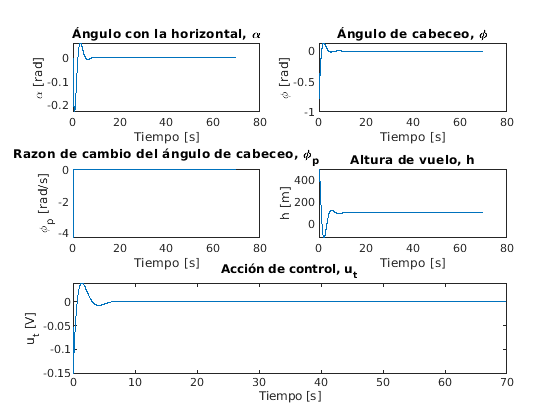

delta = 0.01;
tsim = 70;
N = floor(tsim/delta);
t = 0:delta:(tsim-delta);

% Prealocación de arrelgos
alpha = zeros(1,N);
phi = zeros(1,N);
h = zeros(1,N);
phi_p = zeros(1,N);
u = zeros(1,N);

% Valores iniciales y referencia
ref = 100;
x = [0; 0 ; 0 ; 500];
psita = 0;
% Simulación
for i=1:N
   y_out = Cd*x;
   
   psita_p = ref - y_out(1);
   psita = psita + psita_p;
        
   u(i) = -K'*[x;psita];   
    
   
   x = Ad*x + Bd*u(i);     
   %x  = x + x_p*delta;    
   

   alpha(i) = x(1);
   phi(i)   = x(2);
   phi_p(i) = x(3);
   h(i)     = x(4);    
  
  
   x = [alpha(i); phi(i); phi_p(i); h(i)];
end

figure(2);
hold on
subplot(3,2,1); grid on;
plot(t, alpha);
title('Ángulo con la horizontal, \alpha');
ylabel('\alpha [rad]');
xlabel('Tiempo [s]');

subplot(3,2,2); grid on; 
plot(t, phi);
title('Ángulo de cabeceo, \phi');
ylabel('\phi [rad]');
xlabel('Tiempo [s]');

subplot(3,2,3); grid on; 
plot(t, phi_p);
title('Razon de cambio del ángulo de cabeceo, \phi_p');
ylabel('\phi_p [rad/s]');
xlabel('Tiempo [s]');

subplot(3,2,4); grid on; 
plot(t, h);
title('Altura de vuelo, h');
ylabel('h [m]');
xlabel('Tiempo [s]');

subplot(3,1,3); grid on; 
plot(t, u);
title('Acción de control, u_t');
ylabel('u_t [V]');
xlabel('Tiempo [s]'); hold off

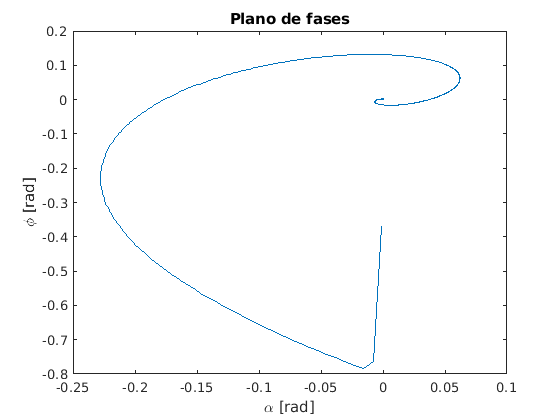


figure(3);
plot(alpha, phi);
title('Plano de fases');
xlabel('\alpha [rad]');
ylabel('\phi [rad]');

Se procede a introducir un observador con las variables observadas siendo $\phi
$ y la altura $h$.

Ao = Ad';
Bo = Cd';
Co = Bd';

Qo = diag([1 1 1 1]);
Ro = diag([1 1]);
Ko = dlqr(Ao, Bo, Qo, Ro)'

Ko =     0.0449    0.0067
    0.0790    0.1599
    0.3750   -5.3613
    1.9836    0.1183


Así, con el observador planteado se simula

N = floor(tsim/delta);
t = 0:delta:(tsim-delta);

% Prealocación de arrelgos
alpha = zeros(1,N);
phi = zeros(1,N);
h = zeros(1,N);
phi_p = zeros(1,N);
u = zeros(1,N);
e_o = zeros(2,N);
% Valores iniciales y referencia
ref = 100;
x = [0; 0 ; 0 ; 500];
x_hat = [0; 0; 0; 0];
psita = 0;

% Simulación
for i=1:N
   y_obs = Cd*x_hat;
   y_out = Cd*x;
   
   psita_p = ref - y_out(1);
   psita = psita + psita_p;
        
   u(i) = -K'*[x;psita];   
    
   e_o(:,i) = y_out - y_obs;
   x = Ad*x + Bd*u(i);      
   x_hat = Ad*x_hat + Bd*u(i) +  Ko*(y_out - y_obs);

   alpha(i) = x(1);
   phi(i)   = x(2);
   phi_p(i) = x(3);
   h(i)     = x(4);    
  
  
   x = [alpha(i); phi(i); phi_p(i); h(i)];
end

figure(4);
hold on
subplot(3,2,1); grid on;
plot(t, alpha);
title('Ángulo con la horizontal, \alpha');
ylabel('\alpha [rad]');
xlabel('Tiempo [s]');

subplot(3,2,2); grid on; 
plot(t, phi);
title('Ángulo de cabeceo, \phi');
ylabel('\phi [rad]');
xlabel('Tiempo [s]');

subplot(3,2,3); grid on; 
plot(t, phi_p);
title('Razon de cambio del ángulo de cabeceo, \phi_p');
ylabel('\phi_p [rad/s]');
xlabel('Tiempo [s]');

subplot(3,2,4); grid on; 
plot(t, h);
title('Altura de vuelo, h');
ylabel('h [m]');
xlabel('Tiempo [s]');

subplot(3,1,3); grid on; 
plot(t, u);
title('Acción de control, u_t');
ylabel('u_t [V]');
xlabel('Tiempo [s]'); 

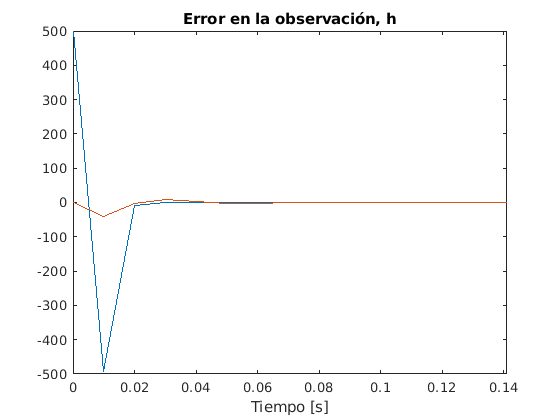

figure(5)
plot(t, e_o);
title('Error en la observación, h');
xlabel('Tiempo [s]');
xlim([0.000 0.141])
ylim([-500 500])

A continuación, se incorpora en la simulacion anterior el efecto de la zona muerta del actuador.

N = floor(tsim/delta);
t = 0:delta:(tsim-delta);

% Prealocación de arrelgos
alpha = zeros(1,N);
phi = zeros(1,N);
h = zeros(1,N);
phi_p = zeros(1,N);
u = zeros(1,N);
e_o = zeros(2,N);
% Valores iniciales y referencia
ref = 100;
x = [0; 0 ; 0 ; 500];
x_hat = [0; 0; 0; 0];
psita = 0;
deathZone = 0.5

deathZone = 0.5000

% Simulación
for i=1:N
   y_obs = Cd*x_hat;
   y_out = Cd*x;
   
   psita_p = ref - y_out(1);
   psita = psita + psita_p;
        
   u(i) = -K'*[x;psita];   
   
   if(abs(u(i))<deathZone)
       u(i) = 0;
   else
       u(i) = sign(u(i))*(abs(u(i)) - deathZone);
   end
   
   e_o(:,i) = y_out - y_obs;
   x = Ad*x + Bd*u(i);      
   x_hat = Ad*x_hat + Bd*u(i) +  Ko*(y_out - y_obs);

   alpha(i) = x(1);
   phi(i)   = x(2);
   phi_p(i) = x(3);
   h(i)     = x(4);    
  
  
   x = [alpha(i); phi(i); phi_p(i); h(i)];
end

figure(5);
hold on

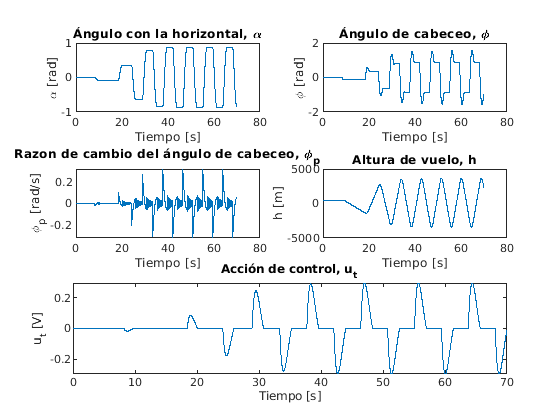

subplot(3,2,1); grid on;
plot(t, alpha);
title('Ángulo con la horizontal, \alpha');
ylabel('\alpha [rad]');
xlabel('Tiempo [s]');

subplot(3,2,2); grid on; 
plot(t, phi);
title('Ángulo de cabeceo, \phi');
ylabel('\phi [rad]');
xlabel('Tiempo [s]');

subplot(3,2,3); grid on; 
plot(t, phi_p);
title('Razon de cambio del ángulo de cabeceo, \phi_p');
ylabel('\phi_p [rad/s]');
xlabel('Tiempo [s]');

subplot(3,2,4); grid on; 
plot(t, h);
title('Altura de vuelo, h');
ylabel('h [m]');
xlabel('Tiempo [s]');

subplot(3,1,3); grid on; 
plot(t, u);
title('Acción de control, u_t');
ylabel('u_t [V]');
xlabel('Tiempo [s]'); 

Como se puede observar, la introduccion de una zona muerta en el actuador de 0.5 produce oscilaciones en la respuesta del sistema, es decir, se aprecian ciclos límites en el sistema. Esto es debido a que la acción de control tiene una magnitud menor a la zona muerta. Estas oscilaciones se pueden corregir subiendo la magnitud de la acción de control para contrarrestar el efecto de la alinealidad del actuador, o buscando un actuador con menor zona muerta.

N = floor(tsim/delta);
t = 0:delta:(tsim-delta);

% Prealocación de arrelgos
alpha = zeros(1,N);
phi = zeros(1,N);
h = zeros(1,N);
phi_p = zeros(1,N);
u = zeros(1,N);
e_o = zeros(2,N);
% Valores iniciales y referencia
ref = 100;
x = [0; 0 ; 0 ; 500];
x_hat = [0; 0; 0; 0];
psita = 0;
deathZone = 0.001 %Bajamos la zona muerta

deathZone = 1.0000e-03

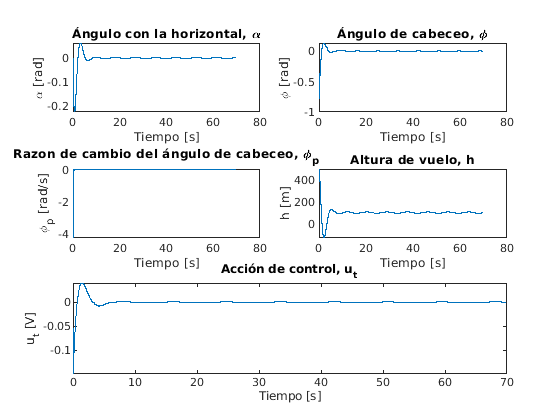

% Simulación
for i=1:N
   y_obs = Cd*x_hat;
   y_out = Cd*x;
   
   psita_p = ref - y_out(1);
   psita = psita + psita_p;
        
   u(i) = -K'*[x;psita];   
   
   if(abs(u(i))<deathZone)
       u(i) = 0;
   else
       u(i) = sign(u(i))*(abs(u(i)) - deathZone);
   end
   
   e_o(:,i) = y_out - y_obs;
   x = Ad*x + Bd*u(i);      
   x_hat = Ad*x_hat + Bd*u(i) +  Ko*(y_out - y_obs);

   alpha(i) = x(1);
   phi(i)   = x(2);
   phi_p(i) = x(3);
   h(i)     = x(4);    
  
  
   x = [alpha(i); phi(i); phi_p(i); h(i)];
end

figure(6);
hold on

subplot(3,2,1); grid on;
plot(t, alpha);
title('Ángulo con la horizontal, \alpha');
ylabel('\alpha [rad]');
xlabel('Tiempo [s]');

subplot(3,2,2); grid on; 
plot(t, phi);
title('Ángulo de cabeceo, \phi');
ylabel('\phi [rad]');
xlabel('Tiempo [s]');

subplot(3,2,3); grid on; 
plot(t, phi_p);
title('Razon de cambio del ángulo de cabeceo, \phi_p');
ylabel('\phi_p [rad/s]');
xlabel('Tiempo [s]');

subplot(3,2,4); grid on; 
plot(t, h);
title('Altura de vuelo, h');
ylabel('h [m]');
xlabel('Tiempo [s]');

subplot(3,1,3); grid on; 
plot(t, u);
title('Acción de control, u_t');
ylabel('u_t [V]');
xlabel('Tiempo [s]'); 